# Shallow-curved shell structure with geometric nonlinearities

See [1] for the details of this model, and [2] for the description of this example.

[1] Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

[2] Cenedese, M., Marconi, J., Haller, G., & Jain, S. (2023). Data-assisted non-intrusive model reduction for forced nonlinear finite elements models. Preprint: [arXiv: 2311.17865](https://arxiv.org/abs/2311.17865) 

The finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

See the `README` of the main repository to retrieve simulations data.

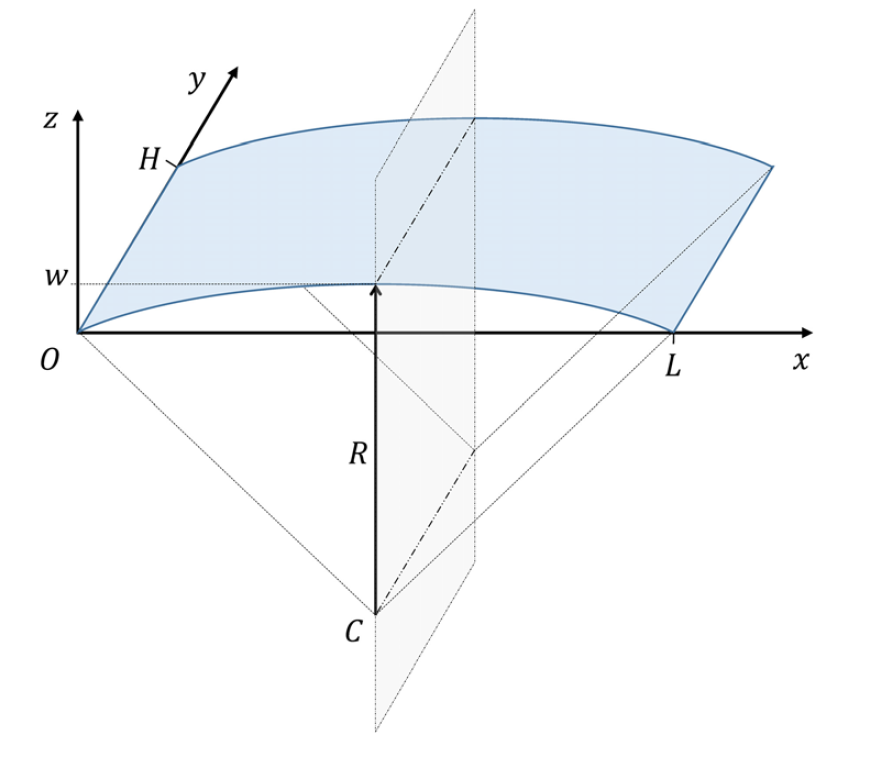

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}   & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}   \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

clearvars 
close all
clc

% Setup colors
colors = colororder; colSSMT = 5; colSSML = 7; colFOM = 1;

## Generate model

Building FE model


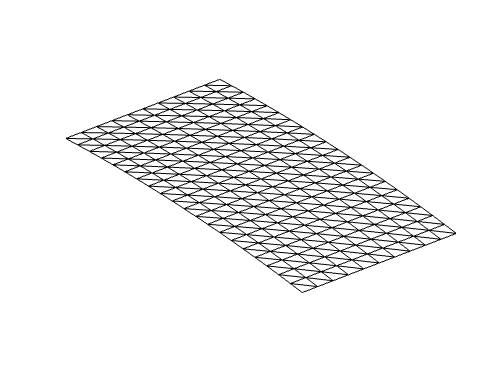

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


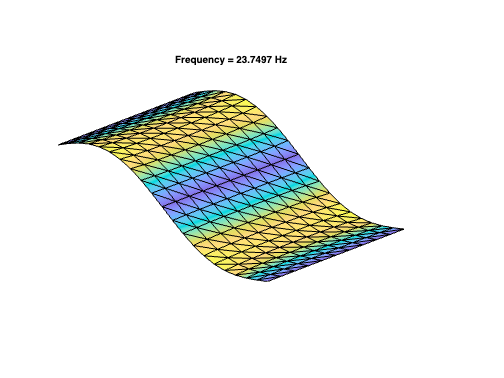

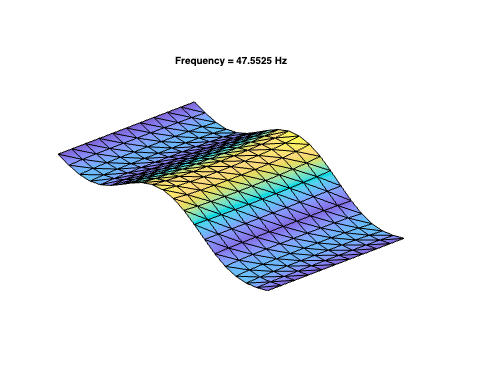

Using Rayleigh damping


a =    8.9285e-06
      0.39808


Assembling external force vector
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:12


nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)
epsilon = 0.1; % converge at order 5
[M,C,K,fnl,f_0,outdof,Model] = buildModel(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


## Linear modal analysis

if ~isfile('linpart.mat')
    m = 10;
    [W,A,V,lambda] = linearpart(M,C,K,m);
    save('linpart.mat',"W","A","V","lambda")
else
    load('linpart.mat')
end

## Define master modes and linear part of the dynamics

We initialize the base properties of the SSM, i.e., its linear part, which we know from the linear dynamics of the model. In this case, we target the slow four-dimensional SSM of the system, which features an internal resonance. 

masterModes = [1 3 2 4]; % Modal displacements and modal velocities
Ve = V(:,masterModes); % Mode shape
We = W(masterModes,:); % Projection to mode shape
Ae = full(We*A*Ve) % Reduced, linearized dynamics

Ae =             0            0            1   2.2546e-14
            0            0    2.213e-14            1
       -22268  -3.2096e-09      -0.5969  -9.5398e-15
  -1.8982e-09       -89270   1.9814e-15      -1.1951


SSMDim = length(masterModes);

displacementVector = zeros(1,n); displacementVector(outdof) = 1;
loadVector = f_0;  %  could also be set as modal ones

## Compare linear and nonlinear response via modal displacement

We characterize the linear and nonlinear regimes via a static modal analysis, which serves to pick appropriate initial conditions for the trajectories we need to learn the SSM from data.

Displacement along the first mode

Solving undamped eigenvalue problem
Eigenfrequency
       149.22



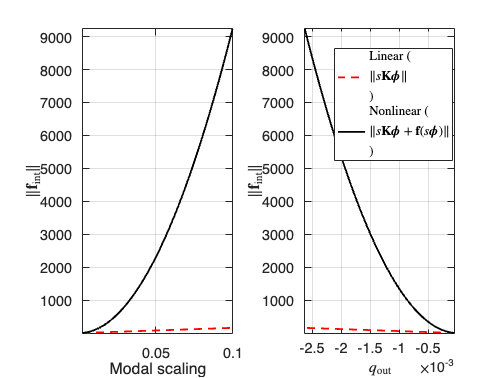

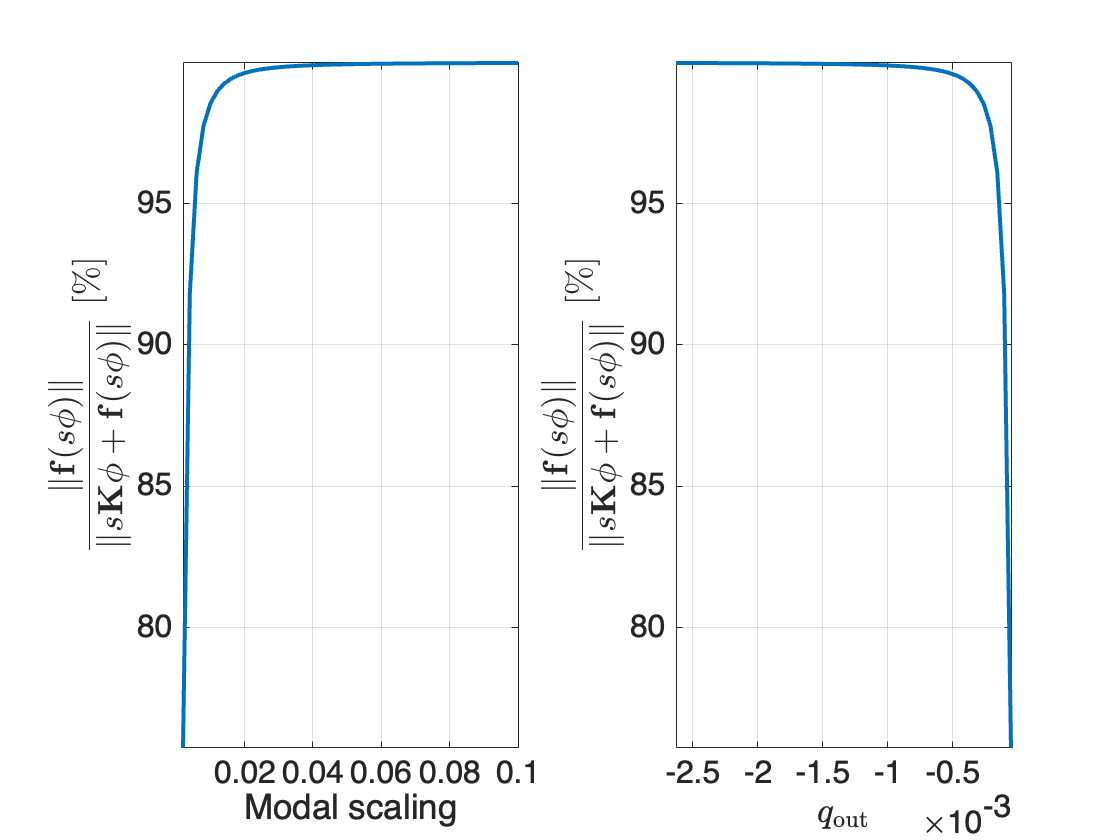

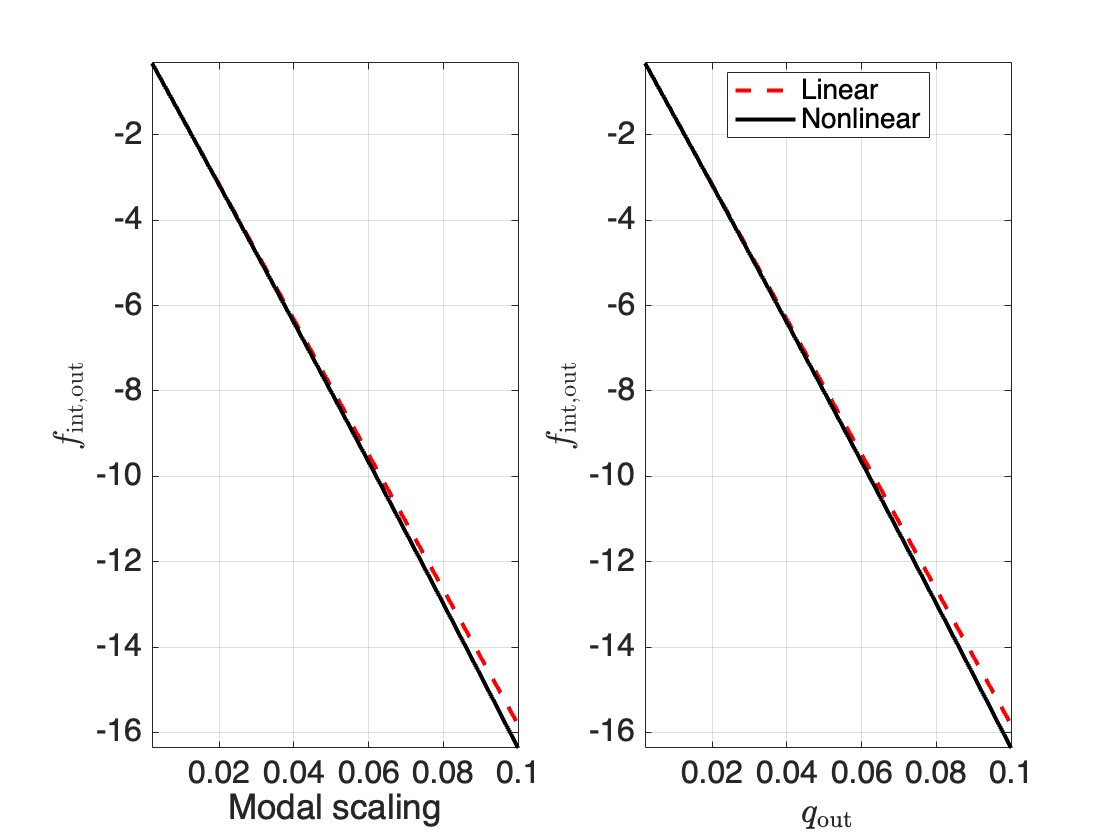

Displacement at output DOF: -0.0026277


iMode = 1; scalingfactor1 = 1e-1; nsteps = 50; outdof1 = outdof(1);
[phi1, relativeDiffForceNorm] = modal_analysis(Model,scalingfactor1,nsteps,outdof1,true,iMode);

Pick up two initial trajectories that has high expected nonlinear content

indIC1 = [nsteps, nsteps-1];
IC1 = [phi1*(scalingfactor1*indIC1/nsteps);zeros(n,length(indIC1))];

Displacement along the second mode

Solving undamped eigenvalue problem
Eigenfrequency
       298.78



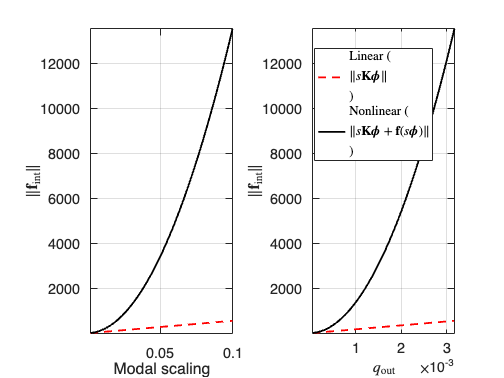

Displacement at output DOF: 0.0031676


iMode = 2; scalingfactor2 = 1e-1; nsteps = 50; outdof2 = outdof(2);
[phi2, relativeDiffForceNorm2] = modal_analysis(Model,scalingfactor2,nsteps,outdof2,true,iMode);

Pick up two initial trajectories that has high expected nonlinear content

indIC2 = [nsteps, nsteps-1];
IC2 = [phi2*(scalingfactor2*indIC2/nsteps);zeros(n,length(indIC2))];

Pick combination of initial conditions along the both the modes for training and testing

a = rand; b = rand; 
ICs = [IC1, IC2, a*IC1 + b*IC2];
indTrain = [1 3 5 6];
indTest = [2 4];

Define the linear regime at 1 % relative force

linearDisplacementReference = scalingfactor1*(sum(relativeDiffForceNorm<1)+1)/nsteps;
nonlinearDisplacementReference = scalingfactor1*max(indIC1)/nsteps;
desiredAmplitudeDecay = nonlinearDisplacementReference/linearDisplacementReference;


## **Generate decaying trajectories via time integration**

We define observables and timescales. The computation of integration time is estimated from the linear decay that gets from the defined nonlinear amplitude to linear regime. We set the sampling time to capture approximately a fixed number points per period on the faster time scale. Then, we integrate using the initial conditions we obtained from the static analysis. Here, we use a pre-computed data set to avoid excessive computations.

observable = @(x) x; % Observe the full phase space
slowTimeScale = 2*pi/abs(lambda(1));
fastTimeScale = 2*pi/abs(lambda(2));
% The computation of integration time is estimated from the linear decay that gets 
% from the nonlinear amplitude to linear regime.
newSimulation = false;
if newSimulation
    numberPeriodsSlow = floor(log(desiredAmplitudeDecay)/...
        (2*pi*(-real(lambda(1))/abs(lambda(1)))))
    endTime = numberPeriodsSlow*slowTimeScale;
    % Set the sampling time to capture approximately 50 points per period on the 
    % faster time scale.
    numberPeriodsFast = floor(endTime/fastTimeScale);
    numberPointsPerPeriod = 50;
    nSamp = numberPeriodsFast*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    xData = integrateTrajectoriesGalphaDirect(Model, endTime, ICs, nSamp, observable);
    loadShape = f_0;
    DataInfo = struct('nElements', Model.Mesh.nElements, 'loadShape', loadShape);
    save('dataVKDecay2DGalphaModal.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp','-v7.3')
else
    load("../../data/vonkarmanshellIR/dataVKDecay2DGalphaModal.mat")
end


## Visualize data

% This step is here not mandatory as we know that the SSM exists in the
% phase space (no embedding needed)
xData = coordinatesEmbedding(xData, SSMDim, 'ForceEmbedding', 1);

The embedding coordinates consist of the measured states.


Data filtering: We need to make sure that the data that we use to identify the manifold lies close to it. We can do this by plotting a spectrogram of the observables of interest. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

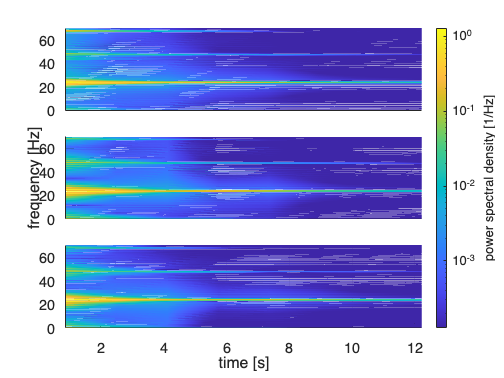

indPlot1 = indTrain(1);
indPlot2 = indTest(1);

% Visualize spectrograms for the first outdof
fig = customFigure();
fontName = 'helvetica';
fontSize = 16;
tiledlayout(3,1);
nexttile
showSpectrogram(xData(1,:), outdof(1), 1);
ylim([0,70])%abs(lambda(1))/2/pi*5])
set(gca, 'fontname', fontName)
set(gca, 'fontsize', fontSize)
xticks([])
nexttile
showSpectrogram(xData(3,:), outdof(1), 1);
ylim([0,70])%abs(lambda(1))/2/pi*5])
set(gca, 'fontname', fontName)
set(gca, 'fontsize', fontSize)
ylabel('frequency [Hz]')
xticks([])
nexttile
showSpectrogram(xData(5,:), outdof(1), 1);
ylim([0,70])%abs(lambda(1))/2/pi*5])
xlabel('time [s]')
cb = colorbar;
cb.Layout.Tile = 'east';
cb.Label.String = 'power spectral density [1/Hz]';
set(gca, 'fontname', fontName)
set(gca, 'fontsize', fontSize)

We plot the observables of interest over time for closer inspection. 

fig = customFigure();
for iTraj = indTrain
    if iTraj == indTrain(1)
        plot(xData{iTraj,1}, xData{iTraj,2}(outdof(1),:),'DisplayName','Training data');
    else
        plot(xData{iTraj,1}, xData{iTraj,2}(outdof(1),:),'HandleVisibility','off');
    end
end
for iTraj = indTest
    if iTraj == indTest(1)
        plot(xData{iTraj,1}, xData{iTraj,2}(outdof(1),:),':','DisplayName','Test data');
    else
        plot(xData{iTraj,1}, xData{iTraj,2}(outdof(1),:),':','HandleVisibility','off');
    end
end
legend('location','NE')
xlabel('$t \, [$s$]$','Interpreter','latex'); ylabel('$q_{\mathrm{out}} \, [$m$]$','Interpreter','latex'); 
title('Generated data')

## Truncate transient data from trajectories

We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval |sliceInt|.

sliceInt = [5*slowTimeScale, endTime];
xDataTrunc = sliceTrajectories(xData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are initialized to lie close to the manifold of interest that is tangent at the origin to the eigenspace spanned by the columns of $\mathbf{V}_e$. 

As we also know the projection $\mathbf{W}_e$ to this eigenspace, we define the modal coordinates as $\mathbf{y} = \mathbf{W}_e \mathbf{x}$. These are the reduced coordinates for our graph style parametrization of the manifold, gauranteed to exists near the origin. We then use the data to learn the nonlinear feature of the manifold geometry, represented via polynomials. Indeed, we seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$\mathbf{x} = \mathbf{V}_e \mathbf{y}  + \mathbf{H}  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where the function $\mathbf{\phi}_{m,2:M}(\mathbf{y})$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $\mathbf{y}$. From SSM theory, the tangent space of the manifold is $\mathbf{V}_e$. The coefficients $\mathbf{H}$are obtained via least squares regression.

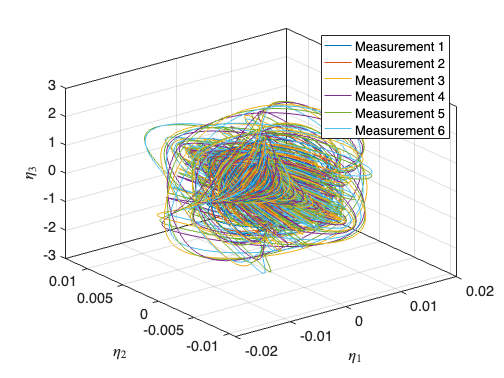

SSMOrder = 2;

% Get projection or modal coordinates 
SSMDim = size(Ve,2);
yDataTrunc = xDataTrunc;
nTraj = size(xDataTrunc,1);
for iTraj = 1:nTraj
    yDataTrunc{iTraj,2} = We*xDataTrunc{iTraj,2};    
end

% Plot reduced coordinates
plotReducedCoordinates(yDataTrunc);
if SSMDim>2
   view(3) 
end


% Compute nonlinear part of the parametrization
IMInfo = IMGeometry(xDataTrunc(indTrain,:), SSMDim,SSMOrder,...
         'reducedCoordinates',yDataTrunc(indTrain,:),'Ve',Ve,'outdof',outdof); 
IMInfo.chart.map = @(x) We*x;                          

% Parametrization error on test trajectory
normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,...
    yDataTrunc), xDataTrunc);
staticNMTE = mean(normedTrajDist(indTest))*100; % in percentage

disp(['Reconstruction error = ' num2str(staticNMTE) '%'])

Reconstruction error = 0.94102%



% Visualize the trajectories in different coordinates
fig = customFigure();
for iTraj = indTrain
    plot3(xData{iTraj,2}(outdof(1),:),xData{iTraj,2}(outdof(1)+size(M,1),:),xData{iTraj,2}(outdof(2),:))
end
xlabel('$q_{A}$ [m]','interpreter','latex')
ylabel('$\dot{q}_{A}$ [m/s]','interpreter','latex')
zlabel('$q_{B}$ [m]','interpreter','latex')
legend('Trajectory 1','Trajectory 2','Trajectory 3')
view(3)


fig = customFigure('subPlot',[3 2]);
for iTraj = [1 3 5]
    subplot(3,2,iTraj)
    plot(xData{iTraj,1}, xData{iTraj,2}(outdof(1),:));
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$q_{out,1} \, [$m$]$','Interpreter','latex'); 
    subplot(3,2,iTraj+1)
    plot(xData{iTraj,1}, xData{iTraj,2}(outdof(2),:));
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$q_{out,2} \, [$m$]$','Interpreter','latex'); 
end

## Reduced dynamics on the manifold

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsMech` finds the dynamics (considering that we know the linear part)

$\dot{\mathbf{y}}= \mathbf{A}_e \mathbf{y}  + \mathbf{H}_r  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where $\mathbf{\phi}(\mathbf{y})$ again computes a vector of all monomials of $\mathbf{u}$, and $\mathbf{H}_r$ is a matrix of polynomial coefficients of the form


$$\mathbf{H}_r = \left[\matrix{  \mathbf{0} \cr  \mathbf{W}_r } \right]$$


Then, we find from data the extended normal form, which expedites system characterization and computation of periodic forced responses.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          6.16336                          29.1
     1           3           4.2627     0.00343599           27.1  
     2           4          3.00363              1           13.9  
     3           5         0.876018              1           7.36  
     4           6          0.67696              1           3.61  
     5           7         0.630143              1           1.83  
     6           8         0.587024              1            2.2  
     7           9         0.504308              1           4.57  
     8          10         0.434066              1           4.08  
     9          11         0.389986              1           1.81  
    10          12         0.365842              1           1.43  
    11          13

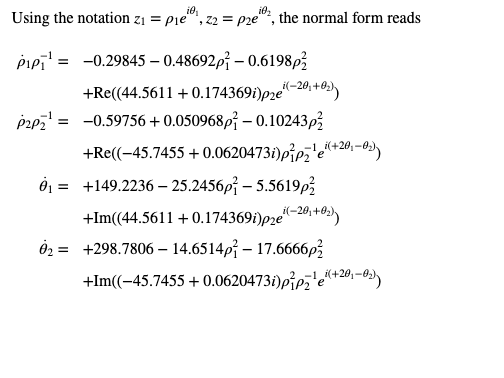

ROMOrder = 3;
freqNorm = [1 2];

RDInfo = IMDynamicsMech(yDataTrunc(indTrain,:), ...
    'R_PolyOrd', 1,'N_PolyOrd', ROMOrder, 'style', 'normalform', ...
    'R_coeff',Ae,'rescale',1,'frequencies_norm',freqNorm,'MaxIter',5e3);


% We transform the truncated initial condition of our test trajectory according to 
% the obtained change of coordinates, and integrate our reduced order evolution rule 
% to predict the development of the trajectory. 
[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, xDataTrunc);

% Evaluation of reduced dynamics
% The error NMTE is computed as the average distance of the predicted trajectory 
% to the measured one in the full state space.
normedTrajDist = computeTrajectoryErrors(yRec, xDataTrunc);
NMTE = mean(normedTrajDist(indTest))*100;
disp(['Normalized mean trajectory error = ' num2str(NMTE) '%'])

Normalized mean trajectory error = 7.1901%


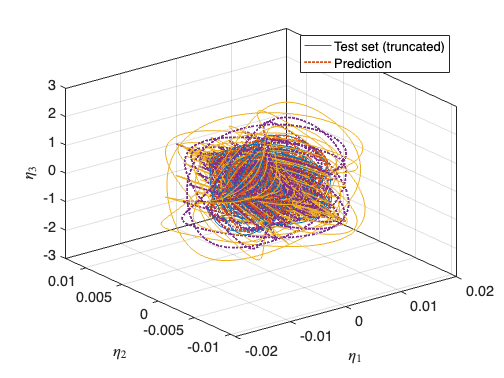


% We plot the true test set trajectory in the reduced coordinates and compare it to 
% the prediction. 
plotReducedCoordinates(yDataTrunc(indTest,:), etaRec(indTest,:))
legend({'Test set (truncated)', 'Prediction'})
if size(Ae,1)==2
    % Plot SSM with trajectories in the normal form reduced coordinates
    plotSSMandTrajectories(IMInfo, outdof, xDataTrunc(indTest,:), ...
        zRec(indTest,:), 'NFT', RDInfo.transformation.map)
    view(-100,20); legend('off')
else
    view(3)
end

We plot the model predictions in physical coordinates. The reduced model seems to do well on previously unseen data, provided that it is close to the manifold.

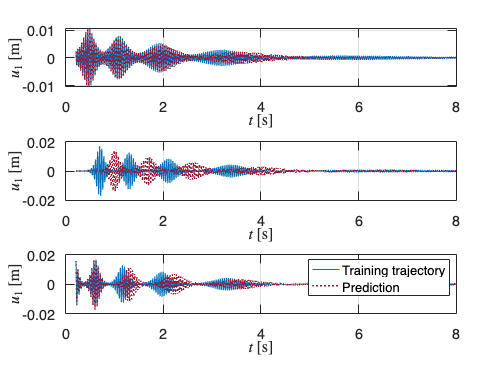

fig = customFigure('subPlot',[3 1]); cc = 0;
for iTraj = [indTrain(1:end-1)+1]
    cc = cc + 1;
    subplot(3,1,cc)
    plot(yDataTrunc{iTraj,1},yDataTrunc{iTraj,2}(1,:),'k','Linewidth',1,'Color',colors(colFOM,:))
    plot(etaRec{iTraj,1},etaRec{iTraj,2}(1,:),':','Linewidth',1.5,'Color',colors(colSSML,:))
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$u_{1}$ [m]','interpreter','latex'); xlim([0 8])
end
legend('Training trajectory','Prediction')

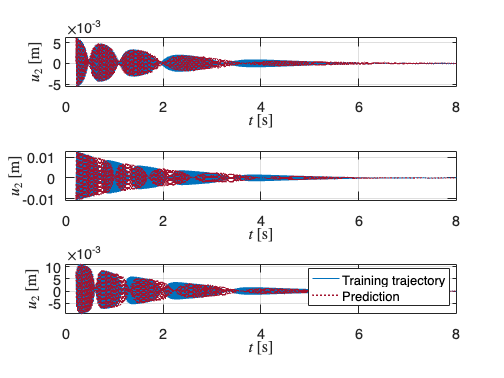

fig = customFigure('subPlot',[3 1]); cc = 0;
for iTraj = [indTrain(1:end-1)+1]  
    cc = cc + 1;
    subplot(3,1,cc)
    plot(yDataTrunc{iTraj,1},yDataTrunc{iTraj,2}(2,:),'k','Linewidth',1,'Color',colors(colFOM,:))
    plot(etaRec{iTraj,1},etaRec{iTraj,2}(2,:),':','Linewidth',1.5,'Color',colors(colSSML,:))
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$u_{2}$ [m]','interpreter','latex'); xlim([0 8])
end
legend('Training trajectory','Prediction')

fig = customFigure('subPlot',[3 1]); cc = 0;
for iTraj = [indTrain(1:end-1)+1]
    cc = cc + 1;
    subplot(3,1,cc)
    plot(xDataTrunc{iTraj,1},xDataTrunc{iTraj,2}(outdof(1),:),'k','Linewidth',1,'Color',colors(colFOM,:))
    plot(yRec{iTraj,1},yRec{iTraj,2}(outdof(1),:),':','Linewidth',1.5,'Color',colors(colSSML,:))
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$q_{A}$ [m]','interpreter','latex'); xlim([0 8])
end
legend('Training trajectory','Prediction')

fig = customFigure('subPlot',[3 1]); cc = 0;
for iTraj = [indTrain(1:end-1)+1]  
    cc = cc + 1;
    subplot(3,1,cc)
    plot(xDataTrunc{iTraj,1},xDataTrunc{iTraj,2}(outdof(2),:),'k','Linewidth',1,'Color',colors(colFOM,:))
    plot(yRec{iTraj,1},yRec{iTraj,2}(outdof(2),:),':','Linewidth',1.5,'Color',colors(colSSML,:))
    xlabel('$t \, [$s$]$','Interpreter','latex'); 
    ylabel('$q_{B}$ [m]','interpreter','latex'); xlim([0 8])
end
legend('Training trajectory','Prediction')

We also check the goodness of fit by evaluating the 1-step prediction error, defined as

$\displaystyle\mathrm{PE}_1^{\mathrm{test}}(t) = \frac{100}{N_{\mathrm{test}}\|\underline{\mathbf{y}}\|}\sum_{k=1}^{N_{\mathrm{test}}} \|\mathbf{y}_k(t)-\hat{\mathbf{y}}(\Delta t;\mathbf{y}_k(t-\Delta t))\|$,

where $N_{\mathrm{test}}$ is the number of test trajectories, $\mathbf{y}_k(t)$ is the $k$-th testing trajectory in reduced coordinates, $\hat{\mathbf{y}}(\Delta t;\mathbf{y}_k(t-\Delta t))$ is the reduced dynamics advection of a sampling time interval $\Delta t$ from the initial condition $\mathbf{y}_k(t-\Delta t)$. We note that, compared to purely linear reduced dynamics, the nonlinear model reduces the 1-step prediction error of one order of magnitude.

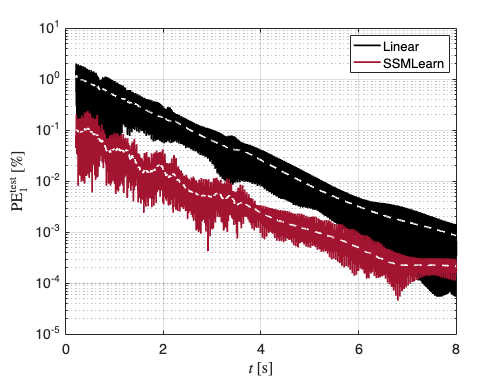

step1error;

## Adding forcing to the ROM

Outer directions: either consider all outer modes or a subset

nModes = size(V,2);
outerModes = setdiff(1:nModes,masterModes);
Vo = V(:,outerModes); 
Wo = W(outerModes,:); Lo = full(Wo*A*Vo);

Forcing vector

forcingVectors = [zeros(n,1); M\loadVector];

Construct time periodic SSM model

[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1,...
         'forcingVectors',forcingVectors,'We',We,'Lo',Lo,'Vo',Vo, 'Wo',Wo);

## Generate Frequency Responses

We compute them also with SSMTool in order to compare the results (see the papers above for additional validations and comparisons).


 Run='SSMLearnFRC.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.83e-01  2.11e+02    0.0    0.0    0.0
   1   1  1.00e+00  1.16e+00  4.28e-02  2.11e+02    0.0    0.1    0.0
   2   1  1.00e+00  4.82e-02  1.76e-03  2.11e+02    0.0    0.1    0.0
   3   1  1.00e+00  2.10e-03  8.06e-08  2.11e+02    0.0    0.1    0.0
   4   1  1.00e+00  2.07e-07  5.37e-14  2.11e+02    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   2.1111e+02      1  EP      1.4922e+02   1.8343e-02   2.2716e-02   2.7527e+00   2.8531e+00   2.0000e-02
    1  00:00:00   2.1108e+02      2  HB      1.4920e+02   1.8611e-02   2.2644e-02   2.7246e+00   2.8534e+00   2.0000e-02
   10  00:00:00   2.1072e+02      3          1.4895e+02   2.2752e-02   2.2534e-

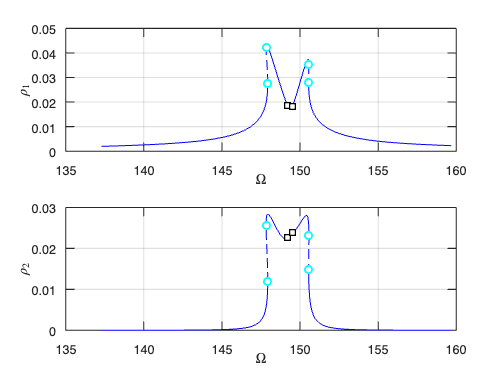

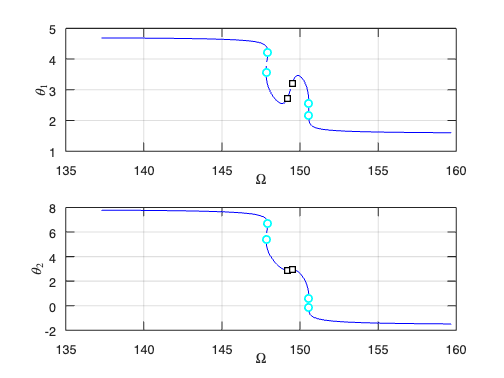


 Run='SSMLearnFRC.ep.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.90e+00  2.11e+02    0.0    0.0    0.0
   1   1  5.56e-01  1.45e+00  1.55e+00  2.11e+02    0.0    0.0    0.0
   2   1  1.00e+00  3.47e-01  3.69e-01  2.11e+02    0.0    0.0    0.0
   3   1  1.00e+00  4.28e-01  8.54e-03  2.11e+02    0.0    0.0    0.0
   4   1  1.00e+00  2.10e-02  2.43e-04  2.11e+02    0.0    0.0    0.0
   5   1  1.00e+00  2.03e-04  2.39e-09  2.11e+02    0.0    0.0    0.0
   6   1  1.00e+00  5.22e-10  4.23e-16  2.11e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   2.1111e+02      1  EP      1.4922e+02   2.8755e-02   5.7950e-02   2.7578e+00   2.7856e+00   7.0000e-02
   10  00:00:00   2.1041e+02      2          1.4875e+02  

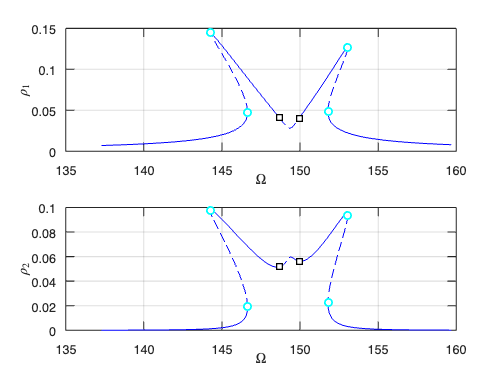

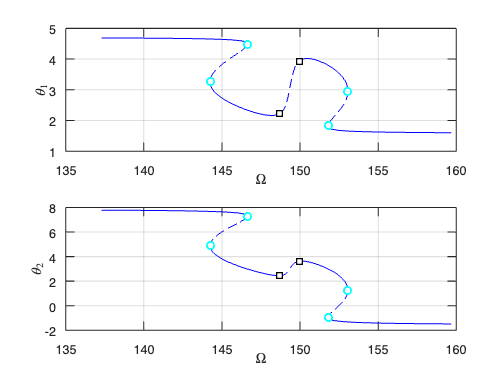

epsilon = [0.02 0.07];
mFreqs = [1 2];
resonantModes = [1 2 3 4];
omegaSpan = [0.92 1.07]*imag(lambda(1));
% SSMLearn
[FRCSSMLearn] = continuationFRCep(IMInfoF, RDInfoF, epsilon, omegaSpan,@(x) x(outdof,:), mFreqs,resonantModes, 'SSMLearnFRC');

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.102524e-03
modal damping ratio for 4 mode is 2.141338e-03
modal damping ratio for 5 mode is 2.369557e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
     -0.29845 +     149.22i
     -0.29845 -     149.22i
     -0.59756 +     298.78i
     -0.59756 -     298.78i
      -0.7143 +     339.73i
      -0.7143 -     339.73i
      -0.7571 +     353.56i
      -0.7571 -     353.56i
      -1.0098 +     426.17i
      -1.0098 -     426.17i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     0     0
     0     0     2     1
     1 

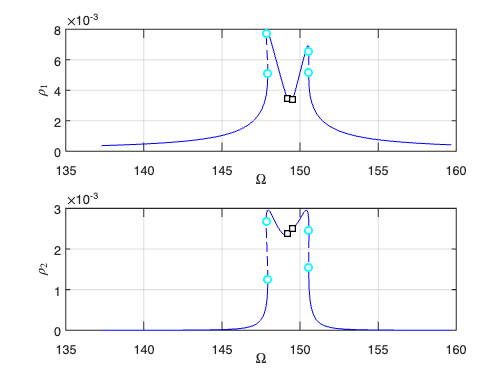

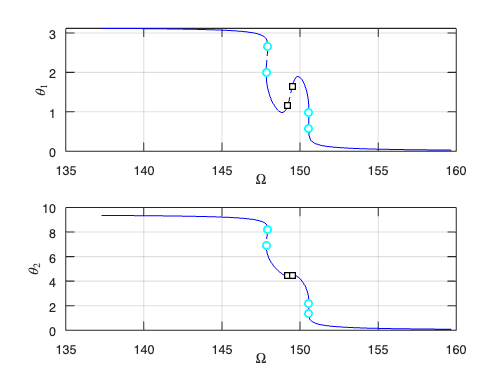

the forcing frequency 1.3729e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3756e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3791e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3826e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3860e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3892e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3924e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3954e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3983e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.4012e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequenc

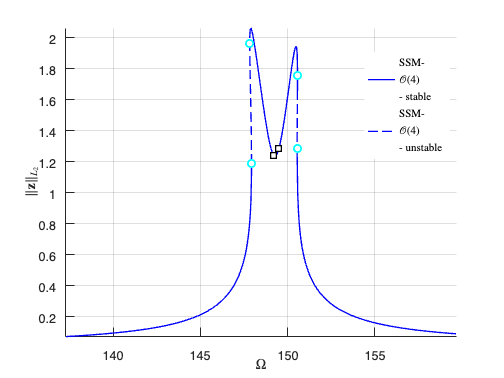

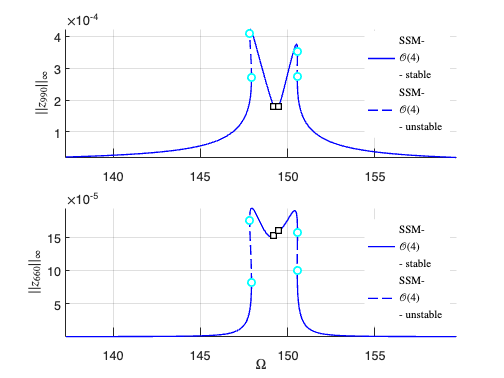

% SSMTool
[FRCSSMTool1] = SSMToolFRCFE(M,C,K,fnl,f_0,outdof,epsilon(1),resonantModes,4,omegaSpan,mFreqs,'SSMToolFRC');

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.102524e-03
modal damping ratio for 4 mode is 2.141338e-03
modal damping ratio for 5 mode is 2.369557e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
     -0.29845 +     149.22i
     -0.29845 -     149.22i
     -0.59756 +     298.78i
     -0.59756 -     298.78i
      -0.7143 +     339.73i
      -0.7143 -     339.73i
      -0.7571 +     353.56i
      -0.7571 -     353.56i
      -1.0098 +     426.17i
      -1.0098 -     426.17i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     0     0
     0     0     2     1
     1 

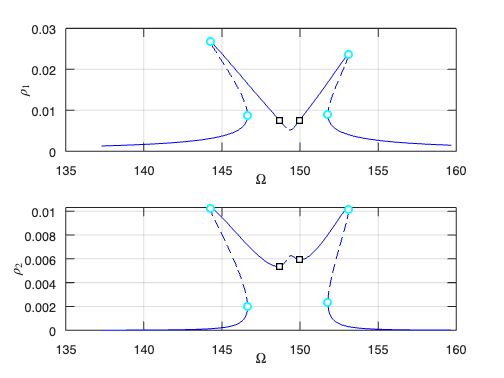

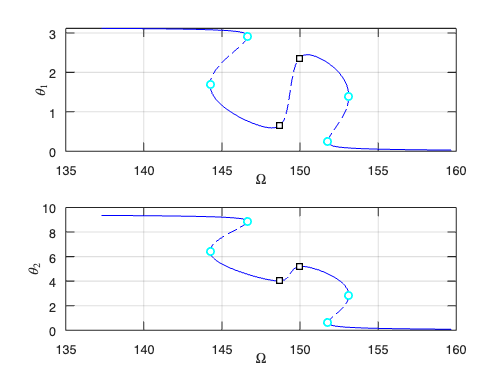

the forcing frequency 1.3729e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3733e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3768e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3804e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3838e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3871e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3903e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3934e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3964e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequency 1.3993e+02 is nearly resonant with the eigenvalue -2.9845e-01 + i1.4922e+02
the forcing frequenc

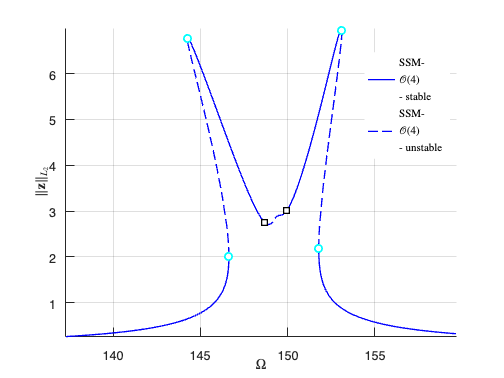

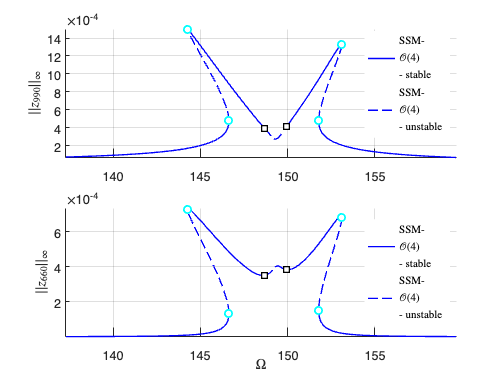

[FRCSSMTool2] = SSMToolFRCFE(M,C,K,fnl,f_0,outdof,epsilon(2),resonantModes,4,omegaSpan,mFreqs,'SSMToolFRC');

FRCSSMTool = struct('F1',FRCSSMTool1.F1,'F2',FRCSSMTool2.F1);

## **Plot results**

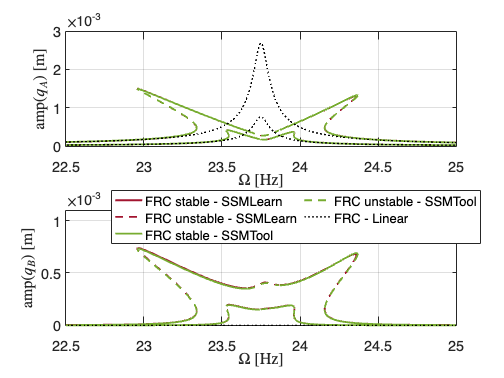

fig = customFigure('subPlot',[2 1]);
subplot(211)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- Tool','freqscale',2*pi)
xlabel('$\Omega$ [Hz]','interpreter','latex')
ylabel('amp($q_{A}$) [m]','interpreter','latex')
legend('off')
xlim([22.5 25])
subplot(212)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','outamp',2,'freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','outamp',2,'freqscale',2*pi)
xlabel('$\Omega$ [Hz]','interpreter','latex')
ylabel('amp($q_{B}$) [m]','interpreter','latex')
xlim([22.5 25])
ylim([0 11e-4])
legend('NumColumns',2)

% Linear Response
LinResp = @(w) (-M*w^2+1i*w*C+K)\(M*forcingVectors(n+1:end));
omegaVec = linspace(omegaSpan(1),omegaSpan(2),1001);
ampVec = zeros(2,length(omegaVec));
for iW = 1:length(omegaVec)
    X0 = abs(LinResp(omegaVec(iW)));
    ampVec(:,iW) = X0(outdof);
end
for iEps = 1:length(epsilon)
    if iEps == 1; visib = 'on'; else; visib = 'off'; end 
    subplot(211)
    plot(omegaVec/2/pi,ampVec(1,:)*epsilon(iEps),'k:','DisplayName', 'FRC - Linear', 'Linewidth', 1.5,'HandleVisibility',visib)
    subplot(212)
    plot(omegaVec/2/pi,ampVec(2,:)*epsilon(iEps),'k:','DisplayName', 'FRC - Linear', 'Linewidth', 1.5,'HandleVisibility',visib)
end

subplot(2,1,2)
legend("Position", [0.22114,0.35539,0.73214,0.14048])